# Neurodata Without Borders Extracellular Electrophysiology Tutorial

## This tutorial

Create fake data for a hypothetical extracellular electrophysiology experiment. The types of data we will convert are:

- Voltage recording

- Local field potential (LFP)

- Spike times

It is recommended to first work through the [Introduction to MatNWB tutorial](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/intro.html), which demonstrates installing MatNWB and creating an NWB file with subject information, animal position, and trials, as well as writing and reading NWB files in MATLAB.

## Setting up the NWB File

An NWB file represents a single session of an experiment. Each file must have a session_description, identifier, and session start time. Create a new [`NWBFile`](https://neurodatawithoutborders.github.io/matnwb/doc/NwbFile.html) object with those and additional metadata. For all MatNWB functions, we use the Matlab method of entering keyword argument pairs, where arguments are entered as name followed by value.

nwb = NwbFile( ...
    'session_description', 'mouse in open exploration',...
    'identifier', 'Mouse5_Day3', ...
    'session_start_time', datetime(2018, 4, 25, 2, 30, 3, 'TimeZone', 'local'), ...
    'timestamps_reference_time', datetime(2018, 4, 25, 3, 0, 45, 'TimeZone', 'local'), ...
    'general_experimenter', 'Last Name, First Name', ... % optional
    'general_session_id', 'session_1234', ... % optional
    'general_institution', 'University of My Institution', ... % optional
    'general_related_publications', 'DOI:10.1016/j.neuron.2016.12.011'); % optional
nwb

nwb =   NwbFile with properties:

                                             nwb_version: '2.6.0'
                                        file_create_date: []
                                              identifier: 'Mouse5_Day3'
                                     session_description: 'mouse in open exploration'
                                      session_start_time: {[2018-04-25T02:30:03.000000+02:00]}
                               timestamps_reference_time: {[2018-04-25T03:00:45.000000+02:00]}
                                             acquisition: [0×1 types.untyped.Set]
                                                analysis: [0×1 types.untyped.Set]
                                                 general: [0×1 types.untyped.Set]
                                 general_data_collection: ''
                                         general_devices: [0×1 types.untyped.Set]
                          general_expe

## Extracellular Electrophysiology

In order to store extracellular electrophysiology data, you first must create an electrodes table describing the electrodes that generated this data. Extracellular electrodes are stored in an `electrodes` table, which is also a [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html). `electrodes` has several required fields: x, y, z, impedence, location, filtering, and electrode_group.

## Electrodes Table

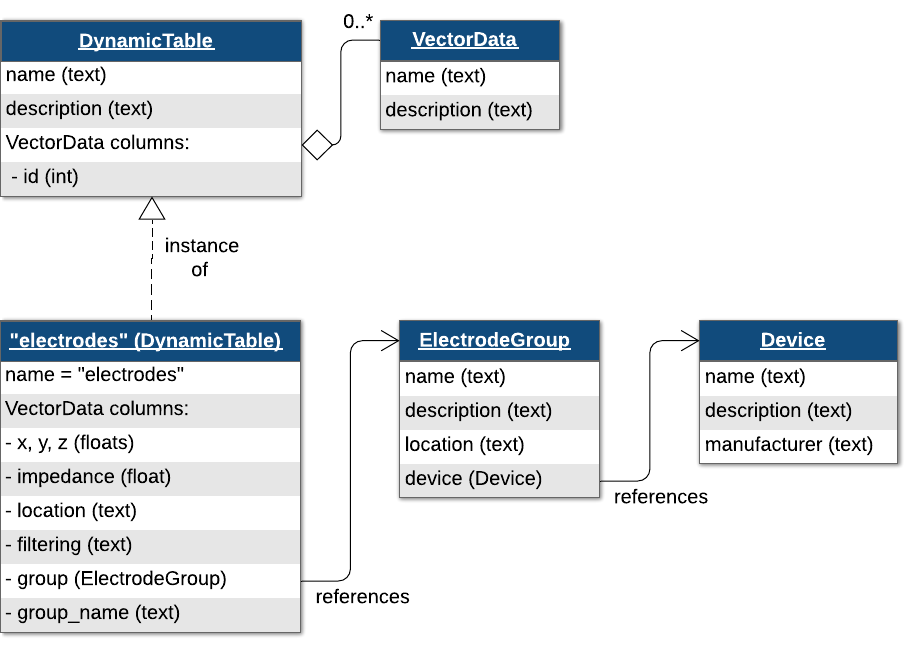

Since this is a [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html), we can add additional metadata fields. We will be adding a "label" column to the table.

Here, we also demonstate another method for creating `DynamicTable`s, by first creating a MATLAB native `Table` object and then calling `util.table2nwb` to convert this `Table` object into a [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html).

numShanks = 4;
numChannelsPerShank = 3;

Electrodes = types.hdmf_common.DynamicTable(...
    'colnames', {'location', 'group', 'group_name', 'label'}, ...
    'description', 'all electrodes');

Device = types.core.Device(...
    'description', 'the best array', ...
    'manufacturer', 'Probe Company 9000' ...
);
nwb.general_devices.set('array', Device);
for iShank = 1:numShanks
    shankGroupName = sprintf('shank%d', iShank);
    Group = types.core.ElectrodeGroup( ...
        'description', sprintf('electrode group for %s', shankGroupName), ...
        'location', 'brain area', ...
        'device', types.untyped.SoftLink(Device) ...
    );
    
    nwb.general_extracellular_ephys.set(shankGroupName, Group);
    for iElectrode = 1:numChannelsPerShank
        Electrodes.addRow( ...
            'location', 'unknown', ...
            'group', types.untyped.ObjectView(Group), ...
            'group_name', shankGroupName, ...
            'label', sprintf('%s-electrode%d', shankGroupName, iElectrode));
    end
end
Electrodes.toTable()

ans = 12×5 table
    id     location                group                group_name      label   
    __    __________    ____________________________    __________    __________

     0    {1×1 cell}    1×1 types.untyped.ObjectView    {1×1 cell}    {1×1 cell}
     1    {1×1 cell}    1×1 types.untyped.ObjectView    {1×1 cell}    {1×1 cell}
     2    {1×1 cell}    1×1 types.untyped.ObjectView    {1×1 cell}    {1×1 cell}
     3    {1×1 cell}    1×1 types.untyped.ObjectView    {1×1 cell}    {1×1 cell}
     4    {1×1 cell}    1×1 types.untyped.ObjectView    {1×1 cell}    {1×1 cell}
     5    {1×1 cell}    1×1 types.untyped.ObjectView    {1×1 cell}    {1×1 cell}
     6    {1×1 cell}    1×1 types.untyped.ObjectView    {1×1 cell}    {1×1 cell}
     7    {1×1 cell}    1×1 types.untyped.ObjectView    {1×1 cell}    {1×1 cell}
  

nwb.general_extracellular_ephys_electrodes = Electrodes;

## Links

In the above loop, we create [`ElectrodeGroup`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectrodeGroup.html) objects. The `electrodes` table then uses an `ObjectView` in each row to link to the corresponding [`ElectrodeGroup`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectrodeGroup.html) object. An `ObjectView` is an object that allow you to create a link from one neurodata type referencing another. 

## ElectricalSeries

Voltage data are stored in [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) objects. [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) is a subclass of [`TimeSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/TimeSeries.html) specialized for voltage data. In order to create our [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) object, we will need to reference a set of rows in the `electrodes` table to indicate which electrodes were recorded. We will do this by creating a [`DynamicTableRegion`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTableRegion.html), which is a type of link that allows you to reference specific rows of a [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html), such as the `electrodes` table, by row indices.

Create a [`DynamicTableRegion`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTableRegion.html) that references all rows of the `electrodes` table.

electrode_table_region = types.hdmf_common.DynamicTableRegion( ...
    'table', types.untyped.ObjectView(electrode_table), ...
    'description', 'all electrodes', ...
    'data', (0:height(tbl)-1)');

Now create an `ElectricalSeries` object to hold acquisition data collected during the experiment.

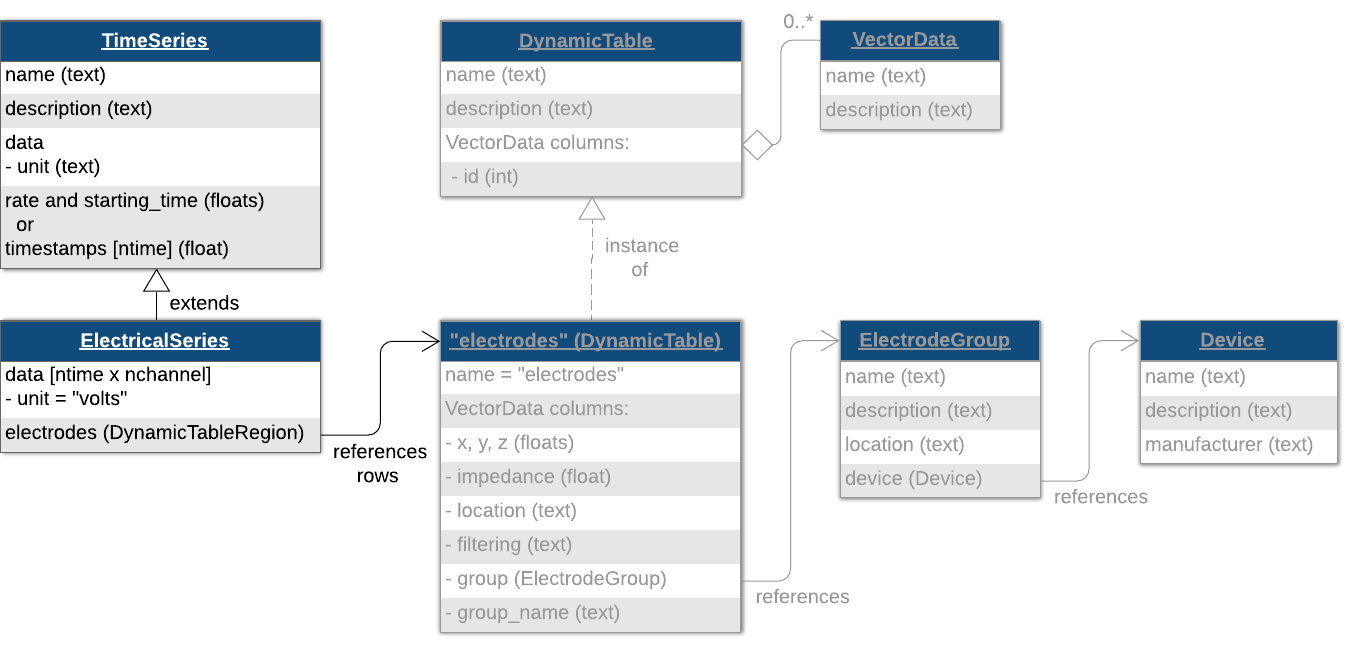

electrical_series = types.core.ElectricalSeries( ...
    'starting_time', 0.0, ... % seconds
    'starting_time_rate', 30000., ... % Hz
    'data', randn(12, 3000), ...
    'electrodes', electrode_table_region, ...
    'data_unit', 'volts');

This is the voltage data recorded directly from our electrodes, so it goes in the acquisition group. 

nwb.acquisition.set('ElectricalSeries', electrical_series);

## LFP

Local field potential (LFP) refers in this case to data that has been downsampled and/or filtered from the original acquisition data and is used to analyze signals in the lower frequency range. Filtered and downsampled LFP data would also be stored in an [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html). To help data analysis and visualization tools know that this [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) object represents LFP data, store it inside an `LFP` object, then place the `LFP` object in a [`ProcessingModule`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ProcessingModule.html) named `'ecephys'`. This is analogous to how we stored the [`SpatialSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/SpatialSeries.html) object inside of a [`Position`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Position.html) object and stored the [`Position`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Position.html) object in a [`ProcessingModule`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ProcessingModule.html) named `'behavior'` earlier.

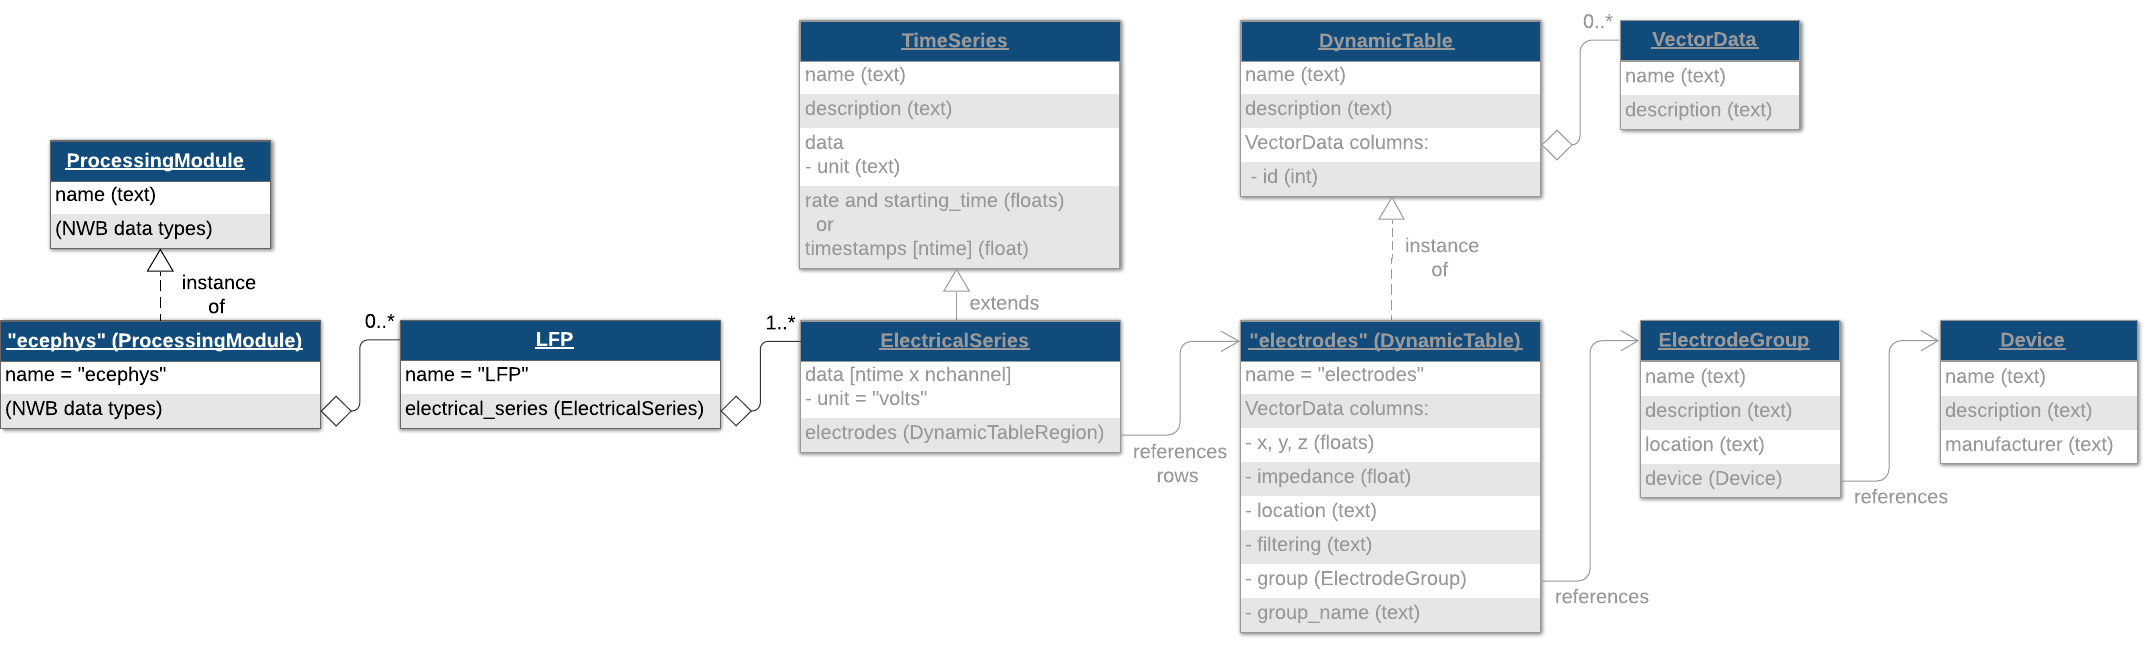

electrical_series = types.core.ElectricalSeries( ...
    'starting_time', 0.0, ... % seconds
    'starting_time_rate', 1000., ... % Hz
    'data', randn(12, 100), ...
    'electrodes', electrode_table_region, ...
    'data_unit', 'volts');

lfp = types.core.LFP('ElectricalSeries', electrical_series);

ecephys_module = types.core.ProcessingModule(...
    'description', 'extracellular electrophysiology');

ecephys_module.nwbdatainterface.set('LFP', lfp);
nwb.processing.set('ecephys', ecephys_module);

## Spike Times

#### Ragged Arrays

Spike times are stored in another [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html) of subtype [`Units`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Units.html). The default `Units` table is at `/units` in the HDF5 file. You can add columns to the [`Units`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Units.html) table just like you did for `electrodes` and `trials`. Here, we generate some random spike data and populate the table. 

num_cells = 10;
firing_rate = 20;
spikes = cell(1, num_cells);
for iShank = 1:num_cells
    spikes{iShank} = rand(1, randi([16, 28]));
end
spikes

spikes = 1×10 cell array
    {[0.1892 0.4707 0.3571 0.6570 0.2082 0.3583 0.7614 0.9778 0.5199 0.5083 0.2594 0.7219 0.2948 0.7529 0.0074 0.8741 0.3734]}    {[0.6774 0.4703 0.6982 0.1011 0.4945 0.6949 0.9875 0.4225 0.0387 0.1020 0.1221 0.8695 0.2595 0.6584 0.4451 0.2202]}    {[0.4886 0.1954 0.8645 0.8686 0.2154 0.7594 0.2697 0.9188 0.8207 0.3690 0.4376 0.0045 0.6200 0.1938 0.7968 0.4089 0.0554 0.5002 0.3852 0.2888 0.0874 0.2219 0.6761 0.1459 0.1451 0.4598]}    {[0.1304 0.2482 0.0361 0.0610 0.7529 0.6503 0.8766 0.1428 0.3190 0.6555 0.8773 0.6792 0.1340 0.5177 0.3988 0.8247 0.2350 0.0863 0.7596 0.6336 0.7986 0.8023]}    {[0.8900 0.7179 0.9761 0.1625 0.6131 0.9465 0.8819 0.8284 0.1747 0.5202 0.7738 0.5095 0.5814 0.0204 0.4214 0.9492 0.5902 0.8666 0.9039 0.7346 0.8106 0.2709 0.8942 0.6940 0.8160]}    {[0.1243 0.1469 0.4422 0.9299 0.9929 0.2198 0.7962 0.8041 0.2607 0.2346 0.4412 0.2641 0.1555 0.5114 0.5614 0.7966 0.8895 0.9246]}    {[0.9033 0.2628 0.2853 0.6505 0.7355 0.4993 0.5396 0.8691 0.5

Spike times are an example of a ragged array- it's like a matrix, but each row has a different number of elements. We can represent this type of data as an indexed column of the units [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html). These indexed columns have two components, the vector data object that holds the data and the vector index object that holds the indices in the vector that indicate the row breaks. You can use the convenience function `util.create_indexed_column` to create these objects.

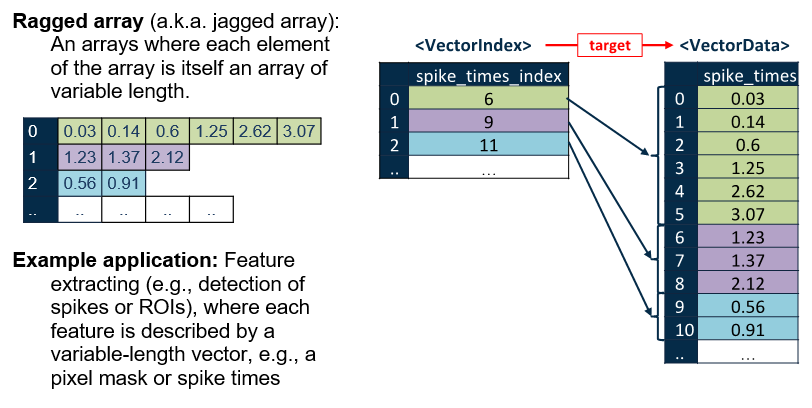

[spike_times_vector, spike_times_index] = util.create_indexed_column(spikes);

nwb.units = types.core.Units( ...
    'colnames', {'spike_times'}, ...
    'description', 'units table', ...
    'id', types.hdmf_common.ElementIdentifiers( ...
        'data', int64(0:length(spikes) - 1) ...
    ), ...
    'spike_times', spike_times_vector, ...
    'spike_times_index', spike_times_index ...
);

## Designating Electrophysiology Data

As mentioned above, [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) objects are meant for storing specific types of extracellular recordings. In addition to this [`TimeSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/TimeSeries.html) class, NWB provides some [Processing Modules](https://pynwb.readthedocs.io/en/stable/tutorials/general/plot_file.html#modules-overview) for designating the type of data you are storing. We will briefly discuss them here, and refer the reader to the [**API documentation**](https://neurodatawithoutborders.github.io/matnwb/doc/index.html) and [**Intro to NWB**](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/intro.html) for more details on using these objects.

For storing spike data, there are two options. Which one you choose depends on what data you have available. If you need to store complete and/or continuous raw voltage traces, you should store the traces with [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) objects as acquisition data, and use the [`EventDetection`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/EventDetection.html) class for identifying the spike events in your raw traces. If you do not want to store the raw voltage traces and only the waveform ‘snippets’ surrounding spike events, you should use the [`EventWaveform`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/EventWaveform.html) class, which can store one or more [`SpikeEventSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/SpikeEventSeries.html) objects.

The results of spike sorting (or clustering) should be stored in the top-level [`Units`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Units.html) table. Note that it is not required to store spike waveforms in order to store spike events or mean waveforms–if you only want to store the spike times of clustered units you can use only the [`Units`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Units.html) table.

For local field potential data, there are two options. Again, which one you choose depends on what data you have available. With both options, you should store your traces with [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) objects. If you are storing unfiltered local field potential data, you should store the [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) objects in [`LFP`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/LFP.html) data interface object(s). If you have filtered LFP data, you should store the [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) objects in [`FilteredEphys`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/FilteredEphys.html) data interface object(s).

## Writing the NWB File

nwbExport(nwb, 'ecephys_tutorial.nwb')

## Reading NWB Data

Data arrays are read passively from the file. Calling `TimeSeries.data` does not read the data values, but presents an HDF5 object that can be indexed to read data. This allows you to conveniently work with datasets that are too large to fit in RAM all at once. `load` with no input arguments reads the entire dataset:

nwb2 = nwbRead('ecephys_tutorial.nwb', 'ignorecache');
nwb2.processing.get('ecephys'). ...
    nwbdatainterface.get('LFP'). ...
    electricalseries.get('ElectricalSeries'). ...
    data.load;

## Accessing Data Regions

If all you need is a data region, you can index a `DataStub` object like you would any normal array in MATLAB, as shown below. When indexing the dataset this way, only the selected region is read from disk into RAM. This allows you to handle very large datasets that would not fit entirely into RAM.

% read section of LFP
nwb2.processing.get('ecephys'). ...
    nwbdatainterface.get('LFP'). ...
    electricalseries.get('ElectricalSeries'). ...
    data(1:5, 1:10)

ans =    -0.6309    1.5217    0.2046   -0.1683    1.4529   -2.7473    0.8611    0.2043   -1.0152    1.6754
    0.7550    0.7684   -0.4529    0.5640    0.6122    0.0932   -0.1549    1.2245   -0.2396   -1.1098
    1.5776   -0.8390    1.0359    1.7682    0.4458    1.1423   -1.2571   -1.4719   -0.0155   -0.2091
    0.3600    1.1862    2.4226    1.7832   -0.7109   -0.0599    0.8568   -0.4077   -0.3402    0.5795
    0.1465   -0.4148    0.9017   -0.5894    0.6480    1.8660    0.4572   -0.5696    0.0443   -1.7328



% You can use the getRow method of the table to load spike times of a specific unit.
% To get the values, unpack from the returned table.
nwb.units.getRow(1).spike_times{1}

ans =     0.1892
    0.4707
    0.3571
    0.6570
    0.2082
    0.3583
    0.7614
    0.9778
    0.5199
    0.5083


# Learn more!

### See the [API documentation](https://neurodatawithoutborders.github.io/matnwb/doc/index.html) to learn what data types are available.

## MATLAB tutorials

- [Optical physiology](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/ophys.html)

- [Intracellular electrophysiology](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/icephys.html)

## Python tutorials

See our tutorials for more details about your data type:

- [Calcium imaging](https://pynwb.readthedocs.io/en/stable/tutorials/domain/ophys.html#sphx-glr-tutorials-domain-ophys-py)

- [Extracellular electrophysiology](https://pynwb.readthedocs.io/en/stable/tutorials/domain/ecephys.html#sphx-glr-tutorials-domain-ecephys-py)

- [Intracellular electrophysiology](https://pynwb.readthedocs.io/en/stable/tutorials/domain/icephys.html#sphx-glr-tutorials-domain-icephys-py)

**Check out other tutorials that teach advanced NWB topics:**

- [Iterative data write](https://pynwb.readthedocs.io/en/stable/tutorials/general/iterative_write.html#sphx-glr-tutorials-general-iterative-write-py)

- [Extensions](https://pynwb.readthedocs.io/en/stable/tutorials/general/extensions.html#sphx-glr-tutorials-general-extensions-py)

- [Advanced HDF5 I/O](https://pynwb.readthedocs.io/en/stable/tutorials/general/advanced_hdf5_io.html#sphx-glr-tutorials-general-advanced-hdf5-io-py)